# Øving 5

## Oppgave 1

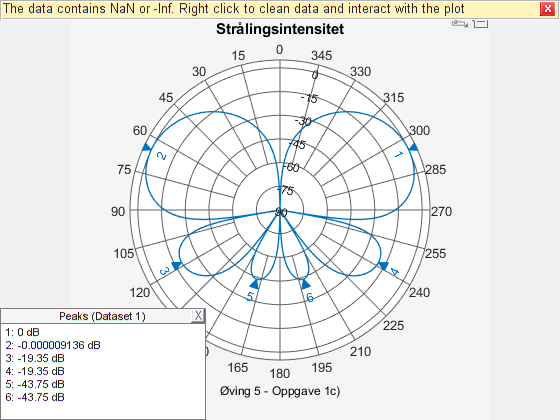

theta = 0:0.001:2*pi;
U = mag2db(abs((sin(theta).* (2 .* sin(pi .* cos(theta)) + 1)).^2));
U = U-max(U);

figure;
p=polarpattern(U);
p.Peaks=6;
p.AngleAtTop=0;
p.MagnitudeLim=[-90,5];
p.MagnitudeTick=-90:15:5;
p.TitleTop='Strålingsintensitet';
p.TitleBottom='Øving 5 - Oppgave 1c)';

## Oppgave 2

% Parameters
N = 6; % Number of elements
alpha = 60; % Maximum pointing angle in degrees
lambda = 1; % Wavelength (normalized to 1 for simplicity)
theta_broadside = pi / 2; % Broadside direction (90 degrees)

% Convert alpha to radians
alpha_rad = deg2rad(alpha);

% Calculate d_max
d_max = lambda * ((1 - 1/N) /  (1 + sin(alpha_rad)));

% Display d_max
fprintf('Maximum element distance (d_max): %.4f\n', d_max);

Maximum element distance (d_max): 0.4466


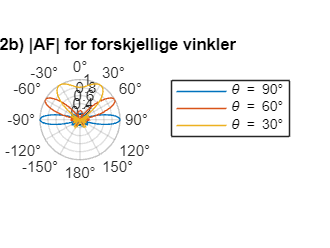


% Steering angles in degrees
steering_angles = [90, 60, 30];
steering_angles_rad = deg2rad(steering_angles);

% Theta values for plotting (from 0 to 360 degrees)
theta = linspace(-pi, pi, 1000); % Modify to range from -pi to pi for symmetry

% Create a polar figure
figure;
pax = polaraxes; % Create polar axes
hold on;

% Adjust polar plot settings
pax.ThetaZeroLocation = 'top'; % Set 0° to point upwards
pax.ThetaDir = 'clockwise';    % Set angle direction to clockwise
pax.ThetaLim = [-180 180];     % Set theta limits to range from -180° to 180°

% Plot array factor for each steering angle
for i = 1:length(steering_angles)
    psi = 2 * pi * d_max * (cos(theta) - cos(steering_angles_rad(i))) / lambda;
    AF = abs(sin(N * psi / 2) ./ sin(psi / 2)); % Array factor formula
    AF = AF / max(AF); % Normalize array factor
    
    % Polar plot
    polarplot(pax, theta, AF, 'DisplayName', sprintf('\\theta = %d°', steering_angles(i)));
end

% Add legend and title
legend('Location', 'bestoutside');
title(pax, 'Oppgave 2b) |AF| for forskjellige vinkler');